Q3

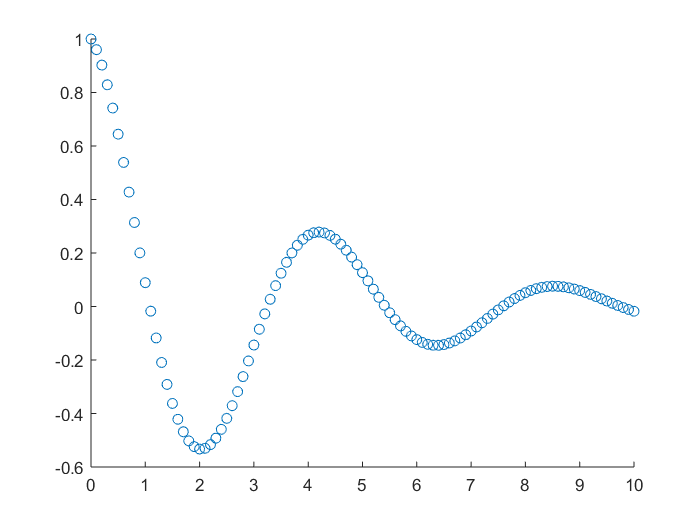

data = importdata('Ass_2_Q3_data.txt');
scatter(data(:,1), data(:,2))

length(data)

ans =    101


roots = [];

x = data(:,1);
f = data(:,2);
for i=2:length(data)
    % we know there is a root if there is a sign change in between points
    if f(i)*f(i-1) < 0
        % run a single iteration of the secant method to find a more
        % precise point
        x_i1 = x(i) - (f(i)*(x(i)-x(i-1))/(f(i)-f(i-1)));
        roots = [roots, x_i1];
    end
end
roots'

ans =    1.083632275955740
   3.250500419428178
   5.416695317223444
   7.583141867942982
   9.750001258406071


T_half = 0;
% calculate the avg half period by using all roots
for i=2:length(roots)
    T_half = T_half + roots(i)-roots(i-1);
end
T_half = T_half/4;
% get the full period
T = T_half*2

T =    4.333184491225166


% find the frequency
f = 1/T

f =    0.230777157544303
